# Creating an Animation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

ike = readtable("./data/ike.csv");
ikeLat = ike.ikeLat;
ikeLon = ike.ikeLon;
ikeWS = ike.ikeWS;

## Task 1

The `geoscatter` function uses a similar syntax to the `scatter` function, including the same three optional inputs that come after you specify the latitude and longitude.

`geoscatter``(``lat``,``lon``,``sz``,``col``,``"filled"``)`

The latitude, longitude, and windspeed measurements of Hurricane Ike are stored in `ikeLat`, `ikeLon`, `ikeWS` respectively.

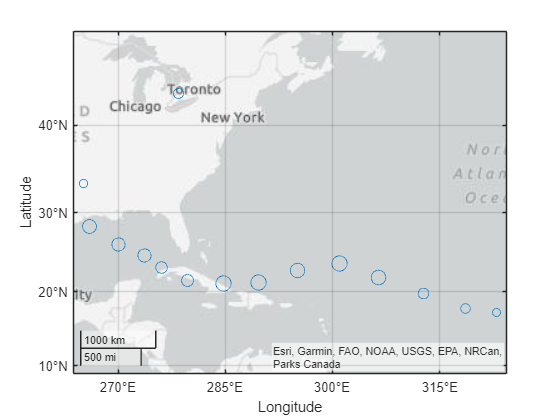

geoscatter(ikeLat, ikeLon, ikeWS);

ax = gca;

## Task 2

MATLAB automatically sets the axes limits based on the data that is currently plotted.  For this animation, you don't want the limits to change in each frame.

The limits are stored in the `LatitudeLimits` and `LongitudeLimits` properties of a `GeographicAxes` object.

latLim = ax.LatitudeLimits;
lonLim = ax.LongitudeLimits;

## Task 3

Now you need to create the initial scatter plot and set the axes limits to prepare to animate data.

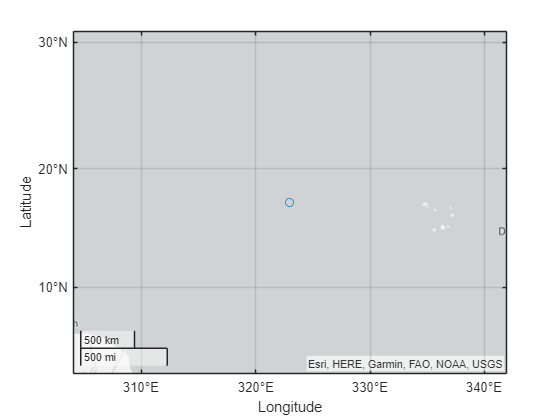

k = 1;
g = geoscatter(ikeLat(k), ikeLon(k), ikeWS(k));

## Task 4

That's just a spot in the middle of the Atlantic with no context for the rest of the trajectory.  Now you can see why you might want to specify the limits in advance.

You can set the limits of a `GeographicAxes` with the `geolimits` function.

`geolimits``(``latLimits``,``lonLimits``)`

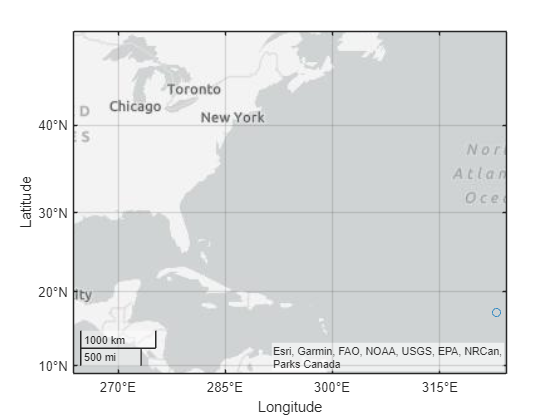

geolimits(latLim, lonLim) 